# Pràctica 6. Exercici 2

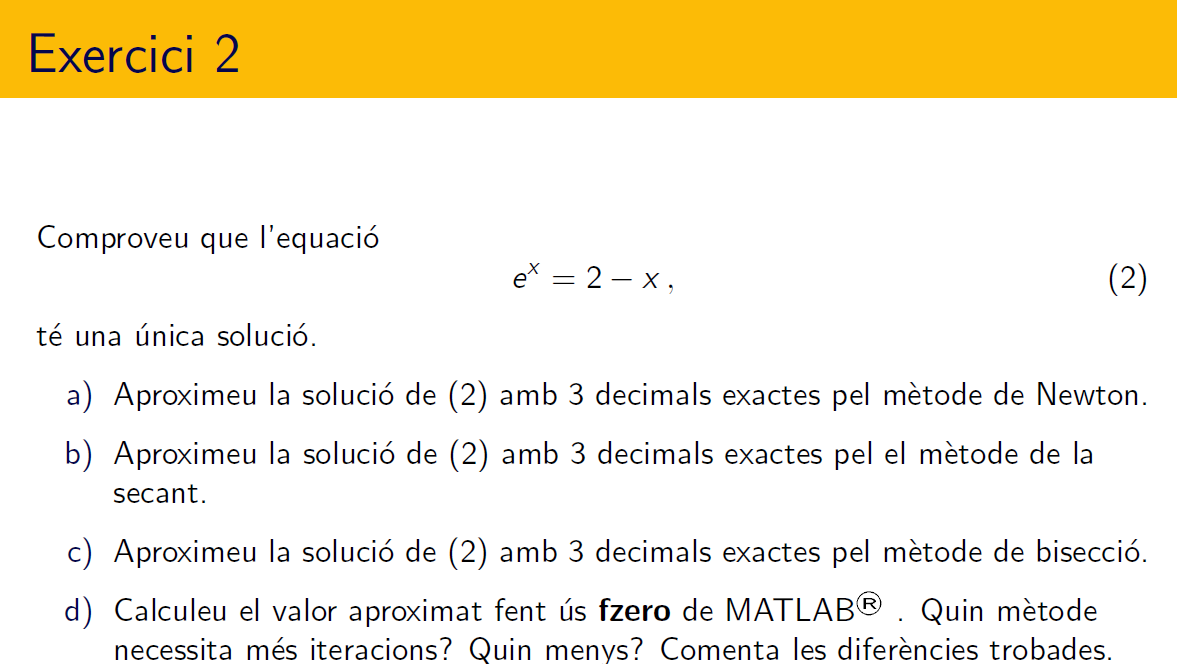

================================================================================

- `Comproveu que l'equació té una solució`

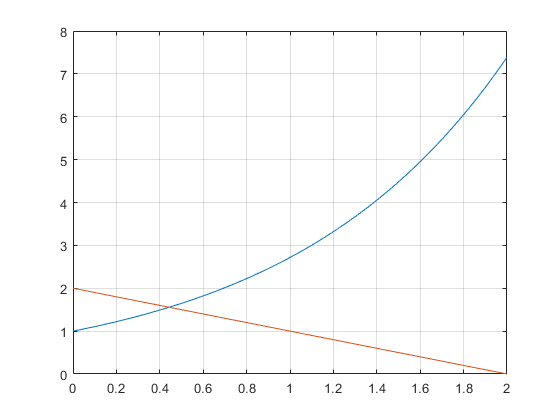

t = linspace(0,2);
plot(t,exp(t),t,2-t),grid

t=(0:0.1:1)';
f = @(x)exp(x)-2+x;
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t       f(t)  
    ___    ________

      0          -1
    0.1    -0.79483
    0.2     -0.5786
    0.3    -0.35014
    0.4    -0.10818
    0.5     0.14872
    0.6     0.42212
    0.7     0.71375
    0.8      1.0255
    0.9      1.3596
      1      1.7183



- `Aproximeu la solució amb tres decimals exactes pel mètode de Newton`

f = @(x) exp(x)+x-2;
fp = @(x) exp(x)+1;
a = 0.4; b = 0.5; n = 50; tol = 0.0005;
newton(f,fp,a,tol,n)

    k          x                   f                   l
    0   0.400000000000000  -0.108175302358730                    
    1   0.443412083707625   0.001426318064278   0.043412083707625
    2   0.442854495698488   0.000000242151722   0.000557588009136
    3   0.442854401002391   0.000000000000007   0.000000094696097


ans =       0.44285


- `Aproximeu la solució amb tres decimals exactes pel mètode de la secant`

f = @(x) exp(x)+x-2;
a = 0.4; b = 0.5; n = 50; tol = 0.0005;
secant(f,a,b,tol,tol,n)

    k          x                   f                   l
        0.400000000000000  -1.081753023587297e-01                    
        0.500000000000000   1.487212707001282e-01                    
    1   0.442108503461409  -1.906935552690836e-03   0.057891496538591
    2   0.442841403066962  -3.323748183503561e-05   0.000732899605553
    3   0.442854403954195   7.548197622497810e-09   0.000013000887232


ans =       0.44285


- `Aproximeu la solució amb tres decimals exactes pel mètode de la bisecció`

f = @(x) exp(x)+x-2;
a = 0.4; b = 0.5; n = 50; tol = 0.0005;
bisect(f,a,b,n,tol)

    k          x                   f                   l
        0.400000000000000  -0.108175302358730                    
        0.500000000000000   0.148721270700128                    
    1   0.450000000000000   0.018312185490169   0.050000000000000
    2   0.425000000000000  -0.045409580336621   0.025000000000000
    3   0.437500000000000  -0.013669701365867   0.012500000000000
    4   0.443750000000000   0.002290801713028   0.006250000000000
    5   0.440625000000000  -0.005697036150776   0.003125000000000
    6   0.442187500000000  -0.001705016764528   0.001562500000000
    7   0.442968750000000   0.000292417216759   0.000781250000000
    8   0.442578125000000  -0.000706418541850   0.000390625000000
        0.442773437500000  -0.000207030360337   0.000195312500000


ans =       0.44277


- `Calculeu el valor aproximat fent ús de ``zeroin/fzero`` de MATLAB®`

f=@(x)x.^6-x-1; 
a=1.1; b = 1.2; 
zeroin(f,a,b)

    1  initial   1.100000000000000  -3.284389999999993e-01
    2  initial   1.200000000000000   7.859839999999993e-01
    3  secant    1.129471663811677  -5.335363960159545e-02
    4  secant    1.135187782354627   4.775145694130734e-03
    5  secant    1.134718216395032  -6.092253217615529e-05
    6  secant    1.134724131768005  -6.824313314446329e-08
    7  secant    1.134724138401614   9.769962616701378e-13
    8  secant    1.134724138401519  -8.881784197001252e-16
    9  minimal   1.134724138401520   1.554312234475219e-15


ans =        1.1347


options = optimset('Display','iter'); % show iterations
[x fval exitflag output] = fzero(f,[a,b],options)

 
 Func-count    x          f(x)             Procedure
    2             1.1     -0.328439        initial
    3         1.12947    -0.0533536        interpolation
    4         1.13482    0.00103201        interpolation
    5         1.13472  -1.31843e-05        interpolation
    6         1.13472  -3.19599e-09        interpolation
    7         1.13472  -8.88178e-16        interpolation
    8         1.13472  -8.88178e-16        interpolation
 
Zero found in the interval [1.1, 1.2]


x =        1.1347


fval =   -8.8818e-16


exitflag =      1


output = struct with fields:
    intervaliterations: 0
            iterations: 6
             funcCount: 8
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [1.1, 1.2]'


[x fval exitflag output] = fzero(f,1,options)

 
Search for an interval around 1 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1               1            -1             1            -1   initial interval
    3        0.971716      -1.12986       1.02828     -0.846116   search
    5            0.96      -1.17724          1.04     -0.774681   search
    7        0.943431      -1.23831       1.05657      -0.66538   search
    9            0.92      -1.31364          1.08     -0.493126   search
   11        0.886863       -1.4003       1.11314     -0.210781   search
   13            0.84       -1.4887          1.16      0.276396   search
 
Search for a zero in the interval [0.84, 1.16]:
 Func-count    x          f(x)             Procedure
   13            1.16      0.276396        initial
   14         1.10989     -0.240576        interpolation
   15         1.13321    -0.0155237        interpolation
   16         1.13473   8.66586e-05        interpolation
   17         1.13

x =        1.1347


fval =   -8.8818e-16


exitflag =      1


output = struct with fields:
    intervaliterations: 6
            iterations: 7
             funcCount: 20
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.84, 1.16]'


- `Quin mètode necessita més iteracions? Quin menys? Comenta les diferències trobades.`

% Cal observar i comentar l'ordre de convergència dels tres mètodes
